clear;
clc;
close all;


## Initialization


%addpath(fullfile(pwd,'\VMS\Capstone'));

datamode = LongOrLat(); % Choose longetudinal or lateral mode
[fileid, pathname] = uigetfile({'*.mat;*.dat'},'File Selector');
if( isa(fileid, 'double') && isequal(fileid, 0) )
    % No file was chosen, so we return
    return
end

[AT, ET, FX, FY, FZ, IA, MX, MZ, N, NFX, NFY, P, RE, RL, RST, SA, SR, TSTC, TSTI, TSTO, V]...
    = ImportRawData(fullfile(pathname, fileid));

data_type = {'  AT'; '  ET'; '  FX'; '  FY'; '  FZ'; '  IA'; '  MX'; '  MZ'; '   N'; ' NFX'; ' NFY'; '   P'; '  RE'; ...
    '  RL'; ' RST'; '  SA'; '  SR'; 'TSTC'; 'TSTI'; 'TSTO'; '   V'; 'index'};

h = height(ET);              % Find Index Length
r =(linspace(1,h,h));        % Make Index Array
r = r';

tableform = [AT, ET, FX, FY, FZ, IA, MX, MZ, N, NFX, NFY, P, RE, RL, RST, SA, SR, TSTC, TSTI, TSTO, V, r];


lbf2N = @(lbf)lbf*4.4482216152605;
N2lbf = @(N)N/4.4482216152605;

psi2kPa = @(psi)psi/0.145037737730217;
kPa2psi = @(kPa)kPa*0.145037737730217;


## Data Separation

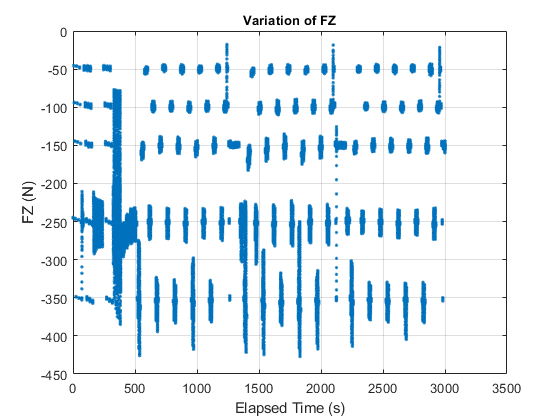

% Normal Force
figure
plot(ET,FZ/4.448,'.'); 
grid on
xlabel('Elapsed Time (s)');
ylabel('FZ (N)');
title('Variation of FZ','FontSize',10);

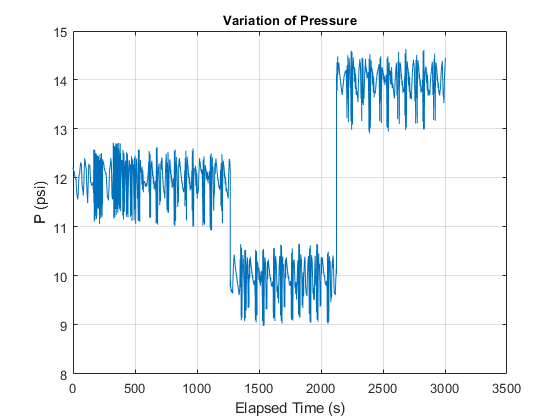


[countsFZ,edgesFZ] = histcounts(N2lbf(FZ));
[~,locsFZ] = findpeaks([countsFZ(2), countsFZ, countsFZ(end-1)]);

% Pressure
figure 
plot(ET,0.145*P);
xlabel('Elapsed Time (s)');
ylabel('P (psi)');
grid on
title('Variation of Pressure','FontSize',10);

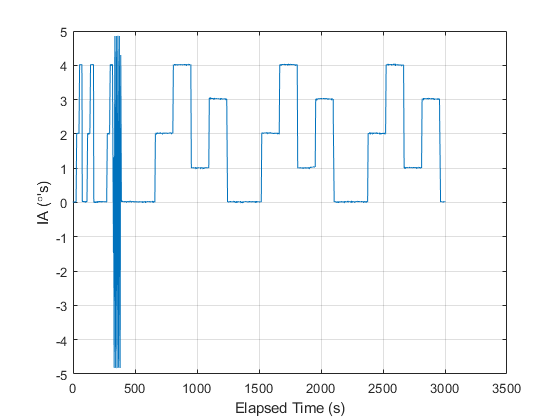


[countsP,edgesP] = histcounts(kPa2psi(P));
[~,locsP] = findpeaks([countsP(2), countsP, countsP(end-1)]);

% Inclination Angle
figure 
plot(ET,IA);
xlabel('Elapsed Time (s)');
ylabel('IA ({\circ}''s)');
grid on

% title('Variation of IA','FontSize',10);

[countsIA,edgesIA] = histcounts(IA);
[~,locsIA] = findpeaks([countsIA(2), countsIA, countsIA(end-1)]);


## Binner

FZ_binvalues = lbf2N(unique(round(abs(edgesFZ(locsFZ)))));
P_binvalues = unique(round(edgesP(locsP)));
IA_binvalues = unique(round(edgesIA(locsIA)));

if( isempty(FZ_binvalues) || isempty(P_binvalues) || isempty(IA_binvalues) )
    error('One or more of the *_binValues arrays was empty.')
end

% Normal Force
FZ_eps1 = lbf2N(35); % Normal force tolerance (N)
FZ_bin = abs(FZ)>((FZ_binvalues-FZ_eps1))&abs(FZ)<((FZ_binvalues+FZ_eps1)); %(N)

% Pressure
P_eps = 0.8;  % Pressure tolerance (psi)
P_bin = kPa2psi(P)>(P_binvalues-P_eps-0.3)&kPa2psi(P)<(P_binvalues+P_eps); %(psi)

% Inclination Angle
IA_eps = 0.2; % Inclination angle tolerance (deg)
IA_bin = (IA>IA_binvalues-IA_eps)&(IA<IA_binvalues+IA_eps); %(deg)

% Zero Slip
if datamode == 1
    S_0 = (-1<SA)&(SA<1);
else
    S_0 = (-1<SR)&(SR<1);
end

% Surface Points
[IA_mat,FZ_mat] = meshgrid(IA_binvalues,FZ_binvalues);


## Preallocate Memory

A = cell(length(P_binvalues),length(IA_binvalues),length(FZ_binvalues));
[S_binfzia, F_binfzia, NF_binfzia, ET_binfzia, FZ_binfzia, IA_binfzia, ...
    MX_binfzia, MZ_binfzia, CS_fzia, mu_fzia, S_H_fzia, S_V_fzia, S_bar_fzia, ...
    F_bar_fzia, B_fzia, C_fzia, D_fzia, E_fzia, F_M, S_M] = deal(A);


## Interface With User


fprintf('   1  AT      7   ME    13     RE    19    TSTI  \n')

   1  AT      7   ME    13     RE    19    TSTI  


fprintf('   2  ET      8   MZ    14     RL    21    TSTO  \n')

   2  ET      8   MZ    14     RL    21    TSTO  


fprintf('   3  FX      9    N    15    RST    22      V   \n')

   3  FX      9    N    15    RST    22      V   


fprintf('   4  FY     10  NFX    16     SA    23   INDEX  \n')

   4  FY     10  NFX    16     SA    23   INDEX  


fprintf('   5  FZ     11  NFY    17     SR                \n')

   5  FZ     11  NFY    17     SR                


fprintf('   6  IA     12    P    18   TSTC                \n')

   6  IA     12    P    18   TSTC                


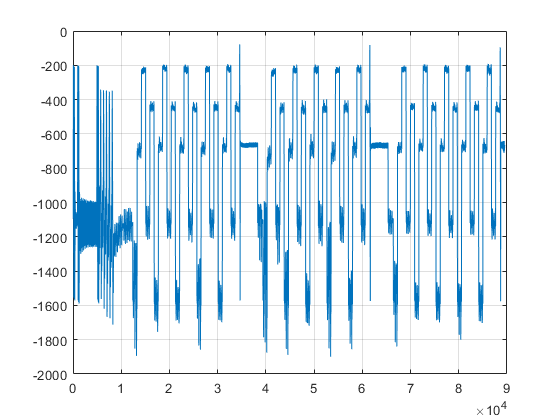


xprompt    = 'X-Axis & Y-Axis Value?';
ind = listdlg('ListString',data_type,'Name','Pressure');
dep = listdlg('ListString',data_type,'Name','Y-Value');

% Prelim
figure
plot(tableform(:,ind),tableform(:,dep)); 
grid on

%xlabel('%d',ind);
%ylabel('%d',dep);
%title('Variation of FZ','FontSize',10);

## Magic Time

for i=1:length(P_binvalues)
    for m=1:size(FZ_bin,2)
        for n=1:size(IA_bin,2)
            validIdx = FZ_bin(:,m) & P_bin(:,i) & IA_bin(:,n) & S_0;
            ET_binfzia{i,n,m}     =  ET(validIdx);  % Time Bins
            FZ_binfzia{i,n,m}     =  FZ(validIdx);  % Vertical Load bins
            IA_binfzia{i,n,m}     =  IA(validIdx);  % Inclination Angle bins
            MX_binfzia{i,n,m}     =  MX(validIdx);  % Overturning Moment bins
            MZ_binfzia{i,n,m}     =  MZ(validIdx);  % Aligning Moment bins
            
            if datamode == 1
                F_binfzia{i,n,m}  =   FX(validIdx);  % Logitudinal Force Bins
                NF_binfzia{i,n,m} =  NFX(validIdx); % Force Coefficient bins
                S_binfzia{i,n,m}  =   SR(validIdx);  % Slip Ratio Bins
            else
                F_binfzia{i,n,m}  =   FY(validIdx);  % Lateral Force Bins
                NF_binfzia{i,n,m} =  NFY(validIdx); % Force Coefficient bins
                S_binfzia{i,n,m}  =   SA(validIdx);  % Slip Angle Bins
            end
        end
    end

%     B_P{i}   = permute(cell2mat(B_fzia(i,:,:)),[3,2,1])';
%     C_P{i}   = permute(cell2mat(C_fzia(i,:,:)),[3,2,1])';
%     D_P{i}   = permute(cell2mat(D_fzia(i,:,:)),[3,2,1])';
%     E_P{i}   = permute(cell2mat(E_fzia(i,:,:)),[3,2,1])';
%     S_S_P{i} = permute(cell2mat(CS_fzia(i,:,:)),[3,2,1])' ./FZ_binvalues;
%     S_V_P{i} = permute(cell2mat(S_V_fzia(i,:,:)),[3,2,1])'./FZ_binvalues;
%     mu_P{i}  = permute(cell2mat(mu_fzia(i,:,:)),[3,2,1])';
%     S_H_P{i} = permute(cell2mat(S_H_fzia(i,:,:)),[3,2,1])'./FZ_binvalues;
%     CS_P{i}  = permute(cell2mat(CS_fzia(i,:,:)),[3,2,1])';        
% 
%     x = IA_binvalues;
%     y = FZ_binvalues;
%     
%     S_H_surf_IA_P{i} = ResponseSurf(S_H_P{i},y,x,2);
%     S_V_surf_IA_P{i} = ResponseSurf(S_V_P{i},y,x,2);
%     Mu_surf_IA_P{i}  = ResponseSurf(mu_P{i},y,x,2);
%     CS_surf_IA_P{i}  = ResponseSurf(CS_P{i},y,x,2);
%     B_surf_IA_P{i}   = ResponseSurf(B_P{i},y,x,2);
%     C_surf_IA_P{i}   = ResponseSurf(C_P{i},y,x,2);
%     D_surf_IA_P{i}   = ResponseSurf(D_P{i},y,x,2);
%     E_surf_IA_P{i}   = ResponseSurf(E_P{i},y,x,2);    
%     Slip_fit = -3:0.01:3;
%     
%     for m=1:length(FZ_binvalues)
%         for n=1:length(IA_binvalues)        
%             [F_M{i,n,m},S_M{i,n,m}] = MagicOutput(MagicFormula([B_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(n)),...
%                 E_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m))],Slip_fit),...
%                 Slip_fit,Mu_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),...
%                 FZ_binvalues(m),CS_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),datamode);
%             
%             if(i==1)
%                 if(m==1 && n==1)
%                     figure
%                     ax1 = axes;
%                     hold on
%                     if datamode == 1
%                         FvsS_Title = 'F_x vs. SR';
%                         yLab = 'F_x (N)'; xLab = 'SR(-)';
%                     else
%                         FvsS_Title = 'F_y vs. SA';
%                         yLab = 'F_y (N)'; xLab = 'SA(-)';
%                     end
%                     title(FvsS_Title);
%                     xlabel(xLab);
%                     ylabel(yLab);
%                     grid on
%                 end
%                 if(n==1)
%                     [Ft,SRt]= MagicOutput(F_bar_fzia{i,n,m},S_bar_fzia{i,n,m},...
%                         Mu_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),...
%                         FZ_binvalues(m),CS_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),datamode);
%                     
%                     % Plotting the Line fit and the Raw Data Points
%                         color = [(linspace(0,1,5))' (linspace(1,0,5))' ([0 .5 1 0.85 0])'];
%                         % Matrix was created to have the same color betweeen data and fit line. Change the amount of values if more colors are needed.
%                     plot(ax1,SRt,Ft,'.','Color',[color(m,1) (color(m,2)) color(m,3)],'HandleVisibility','off');
%                     FZ_binvalues_r = round(FZ_binvalues,2);
%                     plot(S_M{i,n,m}',F_M{i,n,m}','Color',[color(m,1) color(m,2) color(m,3)],'LineWidth',1,...
%                         'DisplayName',[mat2str(FZ_binvalues_r(m)) ' N']);  
%                 end     
%             end
%         end
%     end
%     
%     % Creating the legend for figure. 
%     h = legend(ax1,'show');
%     set(h,'Location','eastoutside');
%     htitle = get(h,'Title');
%     set(htitle,'String','F_z (N)','FontSize',10);                        
%             
%     if(i==1)
%         % Defining figures:
%         [x_plot,y_plot] = meshgrid(0:0.25:4,linspace(FZ_binvalues(1),FZ_binvalues(end),11));      
%         figure
%             ax2 = axes;
%             hold on
%             grid on
%             title('B vs. FZ vs. IA');
%             xlabel('Inclination Angle ({\circ}''s)','Rotation',20);
%             ylabel('F_Z (N)','Rotation',-30);
% %             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
%             zlabel('B (-)');
%             view([-37.5 30]);
%         figure
%             ax3 = axes;
%             hold on
%             grid on 
%             title('C vs. FZ vs. IA');
%             xlabel('Inclination Angle ({\circ}''s)');
%             ylabel('F_Z (N)','FontSize',10,'Rotation',-30);
% %             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
%             zlabel('C (-)');
%             view([-37.5 30]);
% % %  Ommitted due to assumption D = 1
% %         figure
% %             ax4 = axes;
% %             hold on
% %             grid on 
% %             title('D vs. FZ vs. IA','FontSize',10);
% %             xlabel('Inclination Angle ({\circ}''s)','Rotation',20);
% %             ylabel('F_Z (N)','Rotation',-30);
% %             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
% %             zlabel('D (-)','FontSize',10);
% %             view([-37.5 30]);
%         figure
%             ax5 = axes;
%             hold on
%             grid on 
%             title('E vs. FZ vs. IA','FontSize',10);
%             xlabel('Inclination Angle ({\circ}''s)','FontSize',10,'Rotation',20);
%             ylabel('F_Z (N)','Rotation',-30);
% %             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
%             zlabel('E (-)');
%             view([-37.5 30]);
%     end
%     
%     plot3(ax2,IA_mat,FZ_mat,B_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
%         'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
%     mesh(ax2,x_plot,y_plot,(B_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
%         'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
%     plot3(ax3,IA_mat,FZ_mat,C_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
%         'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
%     mesh(ax3,x_plot,y_plot,(C_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
%         'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
% %     plot3(ax4,IA_mat,FZ_mat,D_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
% %         'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
% %     mesh(ax4,x_plot,y_plot,(D_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
% %         'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binValues(i)) ' lbs']);
%     plot3(ax5,IA_mat,FZ_mat,E_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
%         'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
%     mesh(ax5,x_plot,y_plot,(E_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
%         'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
end
% 
% hLegend(1) = legend(ax2,'show');
% hLegend(2) = legend(ax3,'show');
% hLegend(3) = legend(ax4,'show');
% hLegend(4) = legend(ax5,'show');


## Data Export


% % Data Value points
% IA_vect = IA_binvalues;
% FZ_vect = FZ_binvalues;
% 
% % n-D-LookUp Table Output
% bp3d1 = FZ_binvalues;
% bp3d2 = IA_binvalues;
% bp3d3 = P_binvalues;
% 
% B_Lookup3d_map = B_surf_IA_P{1}(IA_mat,FZ_mat);
% C_Lookup3d_map = C_surf_IA_P{1}(IA_mat,FZ_mat);
% D_Lookup3d_map = D_surf_IA_P{1}(IA_mat,FZ_mat);
% E_Lookup3d_map = E_surf_IA_P{1}(IA_mat,FZ_mat);
% 
% for Pidx = 2:numel(P_binvalues)
%     B_Lookup3d_map = cat(3, B_Lookup3d_map, B_surf_IA_P{Pidx}(IA_mat,FZ_mat));
%     C_Lookup3d_map = cat(3, C_Lookup3d_map, C_surf_IA_P{Pidx}(IA_mat,FZ_mat));
%     D_Lookup3d_map = cat(3, D_Lookup3d_map, D_surf_IA_P{Pidx}(IA_mat,FZ_mat));
%     E_Lookup3d_map = cat(3, E_Lookup3d_map, E_surf_IA_P{Pidx}(IA_mat,FZ_mat));
% end
% 
% [pathstr,name,ext] = fileparts(fileid);
% save(fullfile(pwd,'Results',[name '_MagicFormula_datapoints.mat']),...
%     'bp3d1', 'bp3d2', 'bp3d3', 'B_Lookup3d_map', 'C_Lookup3d_map', 'D_Lookup3d_map', 'E_Lookup3d_map');
% save( fullfile(pwd,'Results',[name '_MagicFormula_datasurfaces.mat']),...
%     'B_surf_IA_P','C_surf_IA_P','D_surf_IA_P','E_surf_IA_P');